# 代码

## Task 1: Generate Noise-Disturbed Data

a = load('Realdat.mat')

a = 包含以下字段的 struct :
    blur: [200×200×121 double]


b = load('PSFreal.mat').PSFsmall

b = b(:,:,1) =

    0.0019    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0019    0.0020    0.0020    0.0019    0.0019    0.0019    0.0020    0.0020    0.0020    0.0019    0.0019    0.0019    0.0019    0.0019    0.0020    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0021    0.0020    0.0020    0.0020    0.0019    0.0020    0.0020    0.0020    0.0021    0.0019    0.0018    0.0020    0.0022    0.0021    0.0020    0.0020    0.0019    0.0019    0.0018    0.0018    0.0018    0.0018    0.0019    0.0020    0.0020    0.0020    0.0020    0.0020    0.0019    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0021    0.0020    0.0020    0.0020    

% 选择要可视化的深度（第三维度的索引）

% % 创建三维切片可视化
% figure;
% imagesc(slice);
% colormap gray;  % 选择颜色映射
% colorbar;      % 添加颜色条
% axis equal;    % 设置坐标轴比例一致
% title(['Slice at Depth ', num2str(depth)]);
% xlabel('X');
% ylabel('Y');


% 加载模糊但没有噪声的数据
% simblurNoNoise = load('simblurNoNoise.mat').blur
% psf = load('PSFG&Lsmall.mat').PSFsmall
simblurNoNoise = load('Realdat.mat').blur

simblurNoNoise = simblurNoNoise(:,:,1) =

    0.0029    0.0027    0.0032    0.0032    0.0032    0.0032    0.0031    0.0032    0.0034    0.0029    0.0029    0.0033    0.0032    0.0038    0.0040    0.0035    0.0036    0.0033    0.0043    0.0035    0.0042    0.0042    0.0040    0.0039    0.0041    0.0042    0.0044    0.0044    0.0042    0.0044    0.0041    0.0044    0.0047    0.0053    0.0046    0.0046    0.0049    0.0047    0.0045    0.0052    0.0049    0.0052    0.0060    0.0054    0.0051    0.0060    0.0056    0.0055    0.0063    0.0061    0.0060    0.0050    0.0067    0.0064    0.0061    0.0060    0.0065    0.0062    0.0058    0.0061    0.0064    0.0059    0.0066    0.0067    0.0060    0.0070    0.0069    0.0062    0.0064    0.0055    0.0075    0.0076    0.0072    0.0074    0.0076    0.0072    0.0077    0.0078    0.0074    0.0068    0.0081    0.0074    0.0075    0.0078    0.0079    0.0080    0.0078    0.0079    0.0075    0.0087    0.0082    0.0080    0.0076    0.0081    0.0081    0.00

psf = load('PSFreal.mat').PSFsmall

psf = psf(:,:,1) =

    0.0019    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0019    0.0020    0.0020    0.0019    0.0019    0.0019    0.0020    0.0020    0.0020    0.0019    0.0019    0.0019    0.0019    0.0019    0.0020    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0021    0.0020    0.0020    0.0020    0.0019    0.0020    0.0020    0.0020    0.0021    0.0019    0.0018    0.0020    0.0022    0.0021    0.0020    0.0020    0.0019    0.0019    0.0018    0.0018    0.0018    0.0018    0.0019    0.0020    0.0020    0.0020    0.0020    0.0020    0.0019    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0021    0.0020    0.0020    0.0020

% 调整荧光强度，使图像像素的最终值不超过1
scale_factor = 1 / max(simblurNoNoise(:));
simblurNoNoise = simblurNoNoise * scale_factor; 

wegive = simblurNoNoise(:, :, 4);
% figure;
% imagesc(wegive);
% colormap gray;  
% colorbar;      
% axis equal;    
% title(['Slice at Depth ', num2str(25)]);
% xlabel('X');
% ylabel('Y');

% 添加背景噪声（高斯噪声）
noise_var = 0.01; 
image_with_noise = imnoise(simblurNoNoise, 'gaussian', 0, noise_var);

% 确保图像像素值在0到1之间
image_with_noise(image_with_noise < 0) = 0;
image_with_noise(image_with_noise > 1) = 1;


% 显示添加噪声后的图像
% 获取所选深度的切片
weget = image_with_noise(:, :, 4);

% 创建三维切片可视化
% figure;
% imagesc(weget);
% colormap gray;  
% colorbar;      
% axis equal;   
% title(['Slice at Depth ', num2str(25)]);
% xlabel('X');
% ylabel('Y');

% restore = inverse_filtering(image_with_noise,psf,noise_var);
% imagesc(restore(:,:,4));
% colormap gray;  
% colorbar;      
% axis equal;    
% title(['Slice at Depth ', num2str(25)]);
% xlabel('X');
% ylabel('Y');

restore_wiener = wiener_filtering(image_with_noise,psf,0.05);

NSR = NSR(:,:,1) =

   1.0e+04 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.

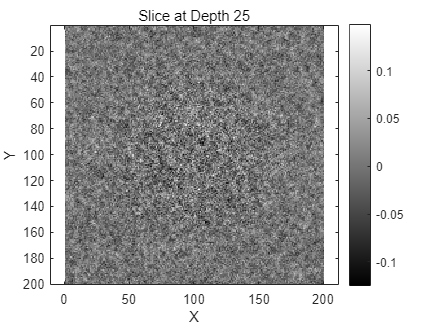

imagesc(restore_wiener(:,:,4));
colormap gray;  
colorbar;      
axis equal;    
title(['Slice at Depth ', num2str(25)]);
xlabel('X');
ylabel('Y');

restored_volume_0 = richardson_lucy(image_with_noise,psf,10);

错误使用 deconvlucy>parse_inputs
在函数 deconvlucy 中，PSF 必须有至少两个元素。

出错 deconvlucy (第 107 行)
    parse_inputs(varargin{:});

出错 untitled>richardson_lucy (第 181 行)
    restored_volume = deconvlucy(observed_volume, psf, iterations);

imagesc(restored_volume_0(:,:,5));
colormap gray;  
colorbar;      
axis equal;    
title(['Slice at Depth ', num2str(25)]);
xlabel('X');
ylabel('Y');

restored_volume = richardson_lucy_3d(10,image_with_noise,psf,noise_var);
imagesc(restored_volume(:,:,4));
colormap gray;  
colorbar;      
axis equal;    
title(['Slice at Depth ', num2str(25)]);
xlabel('X');
ylabel('Y');

## Task 2: Inverse Filtering and Wiener Filtering && Implement R-L Iteration Algorithm (Optional)

function restored_image = inverse_filtering(blurred_image, psf, noise_var)
    img_size = size(blurred_image);
    
    % 将 PSF 转换为 OTF，并确保大小与图像一致
    psf_otf = psf2otf(psf, img_size);
    
    % 将图像转换到频域
    blurred_image_fft = fftn(blurred_image);
    
    % 噪声方差，已知
    N_uv = noise_var;
    
    epsilon = 1e-10;
    inverse_filter = 1 ./ (psf_otf + (N_uv ./ (psf_otf + epsilon)));
    
    % 执行逆滤波
    restored_fft = blurred_image_fft .* inverse_filter;
    
    % 转换回空间域
    restored_image = real(ifftn(restored_fft));
end



function restored_image = wiener_filtering(blurred_image, psf, noise_var)
    img_size = size(blurred_image);
    psf_otf = psf2otf(psf, img_size);

    blurred_image_fft = fftn(blurred_image);

    S_n = noise_var;
    S_f = abs(psf_otf).^2;

    % NSR = S_n ./ (S_f + eps)
    NSR = S_n ./ (abs(psf_otf).^2 +eps)
    H_conj = conj(psf_otf);
    wiener_filter = H_conj ./ (S_f + NSR);

    restored_fft = blurred_image_fft .* wiener_filter;

    restored_image = real(ifftn(restored_fft));
end

function restored_image = richardson_lucy_3d(iterations, observed_volume, psf, noise_var)
    psf_flipped = flip(flip(flip(psf, 1), 2), 3);

    restored_volume = observed_volume;

    for iter = 1:iterations
        % 在更新之前进行简单的噪声平滑处理
        smoothed_volume = imgaussfilt3(restored_volume, sqrt(noise_var));
        
        % 卷积并计算相对误差
        relative_blur = convn(smoothed_volume, psf, 'same');
        error_volume = observed_volume ./ (relative_blur + eps);

        % 使用反转的 PSF 更新估计
        restoration_factor = convn(error_volume, psf_flipped, 'same');
        restored_volume = restored_volume .* restoration_factor;

        % 在更新之后再次进行噪声平滑处理
        restored_volume = imgaussfilt3(restored_volume, sqrt(noise_var));
    end

    % 返回复原的图像
    restored_image = restored_volume;
end



function restored_volume = richardson_lucy(observed_volume, psf, iterations)
    % Richardson-Lucy deconvolution for 3D data
    %
    % Parameters:
    % observed_volume - 3D array of the observed image data
    % psf - Point Spread Function (PSF) corresponding to the system's blurring
    % iterations - Number of iterations to perform
    %
    % Returns:
    % restored_volume - Deconvolved 3D image volume

    % 调用 MATLAB 的 deconvlucy 函数进行 Richardson-Lucy 脱卷积
    % 传入观测图像体积、PSF 和迭代次数
    restored_volume = deconvlucy(observed_volume, psf, iterations);

    % deconvlucy 函数会处理卷积和逆卷积操作，不需要手动进行
end

